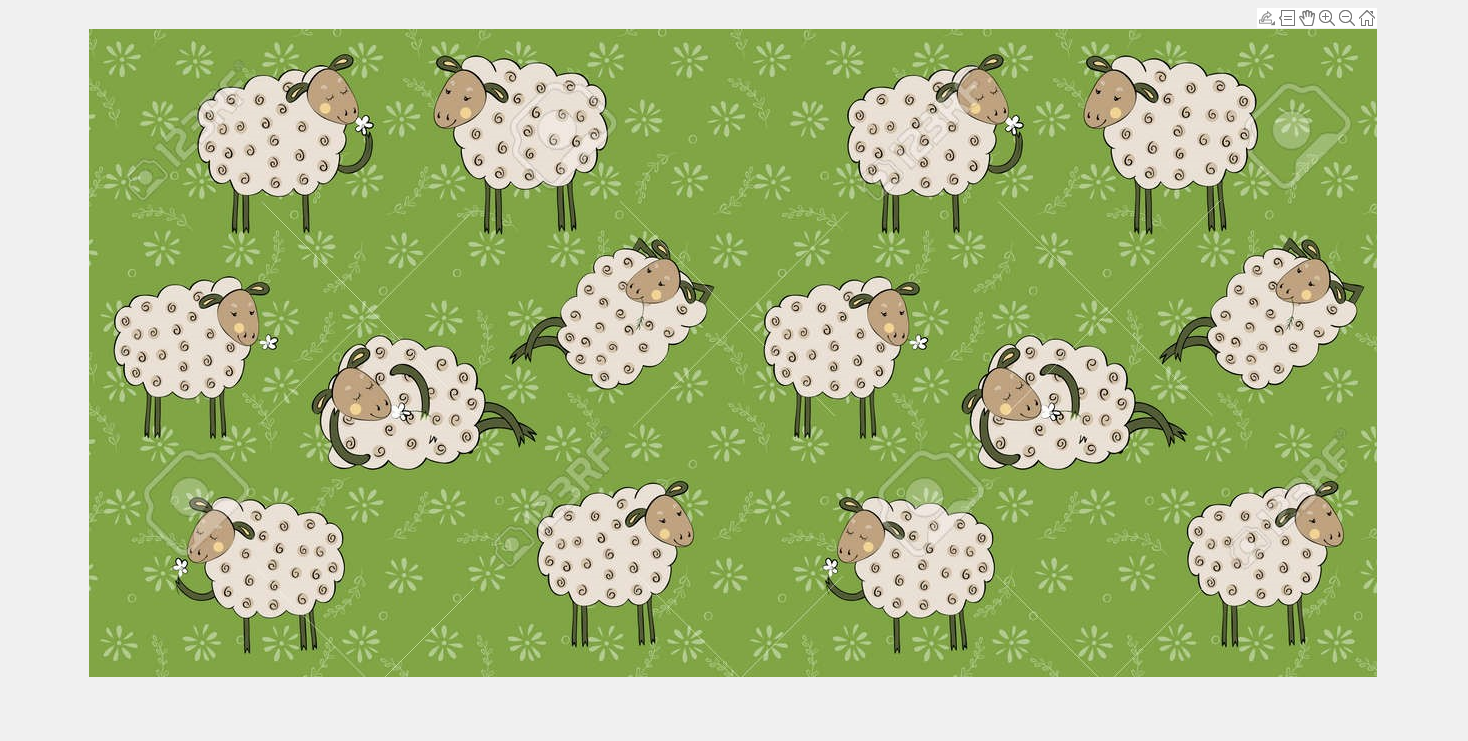

%E9
clear all
S = imread('sheeps.jpg');
imshow(S);
%Idea: usuari selecciona una ovella
%i el sistema detecta totes les altres ovelles
%Per tant extraurem característiques de la imtage
%Ho farem a nivell de grisos perquè serà més ràpid
r = getrect;

Im = rgb2gray(S);
%x columnes y files
I = Im(r(2):r(2)+r(4),r(1):r(1)+r(3));

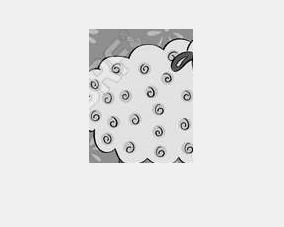

imshow(I);

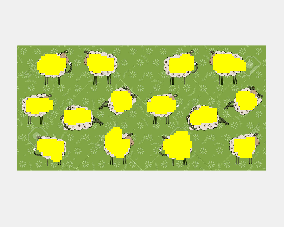

%Volem que ens donin una descripció numérica de la imatge
D = mydescriptor(I);
step = 10;
h = round(r(4)/2-step/2);
w = round(r(3)/2-step/2);
blk = [h,w];
R = blkproc(Im, [step step], blk, @mycompareimage, D);

%La imatge resultant és més petita atès que estem fent pasos de 10 en 10
%Anem a comparar-la amb la imatge original
R = imresize(R,size(Im));
B = imoverlay(S,R,'yellow');
imshow(B);